## 1 THEORY

% 1
J_train=-log(0.1)

J_train = 2.3026


% 3
% name the confusion matrix A
A = [5 2 3 4;
    8 12 30 4;
    0 8 45 4;
    10 0 5 80];
% class prior
class_sum = sum(A);
prior = class_sum/sum(class_sum)

prior =     0.1045    0.1000    0.3773    0.4182


% overall accuracy
overall_acc = sum(diag(A))/sum(sum(A))

overall_acc = 0.6455

## 2 Gradient Descent

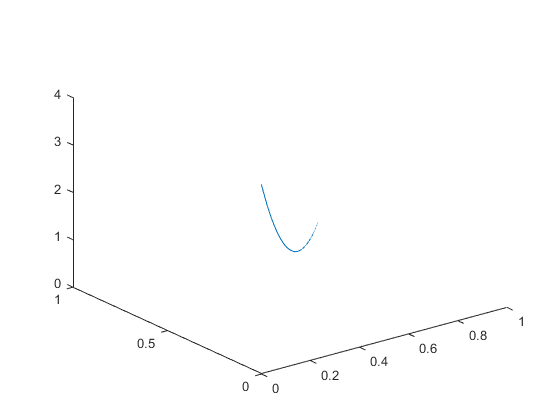

theta = [0 0];
Jo_train = (0+0-2)^2;
J_train = [Jo_train];
N=2000; % maximum number of iteration
eps = 1e-6; % precision of paramters and J
rate = 0.01; % learning rate

% initialization
theta_step_norm = 1; 
J_diff = 1;
k=1;

while k<N && theta_step_norm >eps && J_diff>eps    % termination criterion
    theta_step = rate*2*(sum(theta(k,:))-2);
    theta_step_norm = norm(theta_step);
    k=k+1;
    theta(k,:) = theta(k-1,:)-theta_step;
    J_train(k) = (sum(theta(k,:))-2)^2;
    J_diff = abs(J_train(k)-J_train(k-1));
end

% plot
plot3(theta(:,1),theta(:,2),J_train)

xlabel('\theta_1')
ylabel('\theta_2')
zlabel('J')

## 3 Gradient Descent Logistic Regression

###  read data

cd 'yalefaces'
files = ls;    % list all files
X = zeros(154,1600);
y = zeros(154,1);
k=0;
for ii=1:length(files)  % channel
    if startsWith(files(ii),'s') % get all files start with 's' 
        k=k+1;
        file = files(ii,:);
        title= split(file,{'.',' '});
        score= str2double(regexprep(title{1},['^' 'subject'],'')); % strip prefix 'subject'
        y(k)=score;
        
        fileArray = imread(file);
        fileArrayReduced = imresize(fileArray,[40 40]); % resize
        X(k,:) = fileArrayReduced(:);         % transfer to 1-D array
    end
end
cd ../

### Data preperation

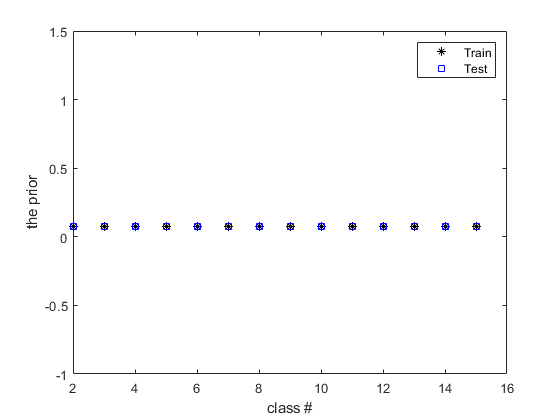

% randomize the data
rng(20)  % random state
idx = randperm(154);
X = X(idx,:);
y = y(idx);

% number of classes
[~,GR] = groupcounts(y);
K = length(GR);

% split the train adn test dataset
ratio  = 2/3;
X_train = [];
y_train = [];
X_test = [];
y_test = [];   

% devide the data class-wise to ensure train adntest has close/identical priors
for ii=1:K
    idx_class_ii = find(y == GR(ii)); % find the idx for class GR(ii)
    N_class_ii = length(idx_class_ii);
    split_num = round(N_class_ii*ratio);
    X_train = [X_train;X(idx_class_ii(1:split_num),:)];
    y_train = [y_train;y(idx_class_ii(1:split_num))];
    X_test = [X_test;X(idx_class_ii(split_num+1:N_class_ii),:)];
    y_test = [y_test;y(idx_class_ii(split_num+1:N_class_ii))];    
end

% check the prior for each class in train and test set
[GC_train,GR_train] = groupcounts(y_train);
[GC_test,GR_test] = groupcounts(y_test);
Num_train = size(X_train,1); % size of train dataset
plot(GR_train,GC_train/Num_train,'k*')
hold on
plot(GR_test,GC_test/(size(X,1)-Num_train),'bs')
xlabel('class #')
ylabel('the prior')
legend('Train','Test')
hold off



% also check the mac value, in which 1 means identical, 0.9 typically mean good correlation
mac = (GC_train/Num_train)'*(GC_test/(154-Num_train)) / norm(GC_train/Num_train)/norm(GC_test/(154-Num_train))

mac = 1.0000


% standerize the dataset and add bias
mean_train = mean(X_train);
std_train = std(X_train);
X_train_S = (X_train-mean_train)./std_train; % standerdize
X_train_S(:,end+1)=1; % add bias in the end
X_test_S = (X_test - mean_train)./std_train;
X_test_S(:,end+1) = 1; % add bias for test data set

### Data Analysis

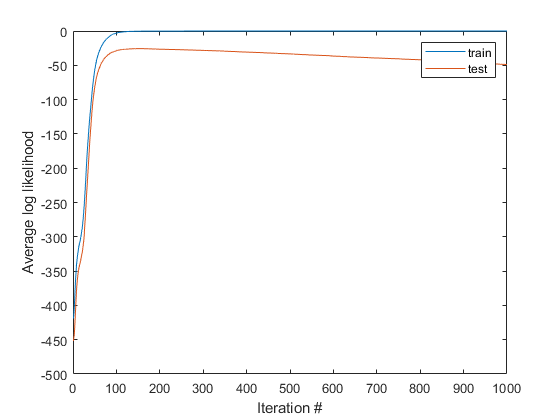

% termination parameters
N=1000; % maximum number of iteration
eps = 1e-6; % precision of paramters and J
rate = 0.1; % learning rate
alpha = 0.01; % blending factor

% initialization
rng(1)
theta =rand(1601,K);
J_train = log_likelihood(X_train_S,theta,y_train,GR);
J_test = log_likelihood(X_test_S,theta,y_test,GR);
theta_step_norm = 1; 
J_diff = 1;
k=1;

while k<N && theta_step_norm >eps && J_diff>eps    
    gradient = batch_gradient(X_train_S,theta,y_train,GR,alpha);
    theta_step = rate*gradient;
    theta_step_norm = norm(theta_step,1)/1601;
    k=k+1;
    theta = theta + theta_step;
    J_train(k) = log_likelihood(X_train_S,theta,y_train,GR_test);
    J_diff = abs(J_train(k)-J_train(k-1));
    J_test(k) = log_likelihood(X_test_S,theta,y_test,GR);
end

plot(1:k,J_train)
hold on
plot(1:k,J_test)
hold off
xlabel('Iteration #')
ylabel('Average log likelihood')
legend('train','test')

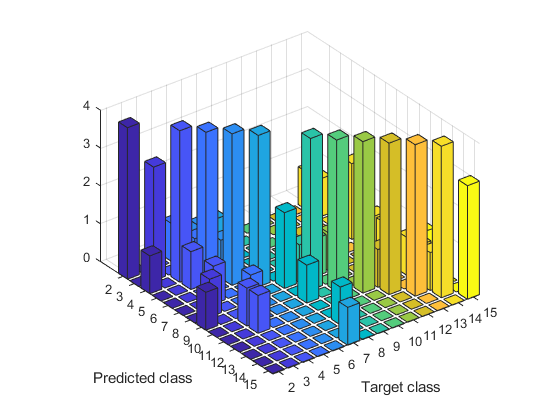


% compuate the accuracy for test dataset
y_p = 1./(1+exp(-X_test_S*theta));
y_b = binary_vector(y_test,GR);
CM = confusionMatrix(y_p,y_b);
bar3(GR,CM(1:end-1,1:end-1))
set(gca,'XTickLabel',GR)
xlabel('Target class')
ylabel('Predicted class')


Overall_acccuracy = CM(end,end)

Overall_acccuracy = 0.9286

L2 = diag(0.5*(theta'*theta))

L2 =   658.2359
  576.2786
  586.8544
  699.1259
  667.3812
  586.4511
  619.5650
  679.6679
  610.3815
  686.7185


## 4 Gradient Descent w/ Softmax and Cross-Entropy

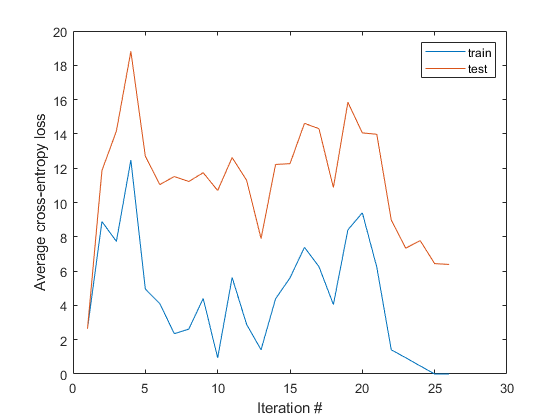

% termination parameters
N=1000; % maximum number of iteration
eps = 1e-6; % precision of paramters and J
rate = 0.08; % learning rate
alpha =0.85; % blending factor

% initialization
rng(3)
theta =zeros(1601,K);
[J_train,gradient] = cross_entropy_loss(X_train_S,theta,y_train,GR,alpha);
[J_test,~] = cross_entropy_loss(X_test_S,theta,y_test,GR,alpha);

theta_step_norm = 1; 
J_diff = 1;
k=1;

while k<N && theta_step_norm >eps && J_diff>eps    
    theta_step = rate*gradient;
    theta_step_norm = norm(theta_step,1)/1601;
    k=k+1;
    theta = theta - theta_step;
    [J_train(k) ,gradient] = cross_entropy_loss(X_train_S,theta,y_train,GR,alpha);
    J_diff = abs(J_train(k)-J_train(k-1));
    [J_test(k),~] = cross_entropy_loss(X_test_S,theta,y_test,GR,alpha); % J for test dataset
end

plot(1:k,J_train)
hold on
plot(1:k,J_test)
hold off
xlabel('Iteration #')
ylabel('Average cross-entropy loss')
legend('train','test')

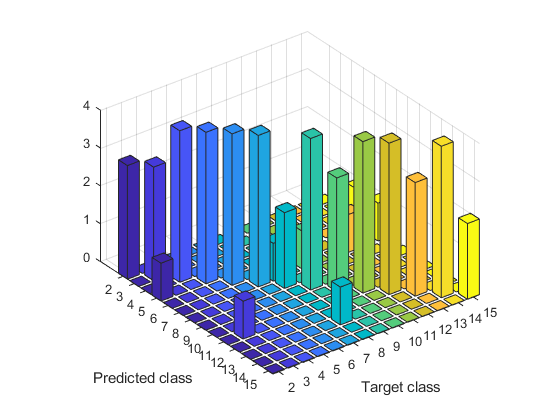


% compuate the accuracy for test dataset
y_p = exp(X_test_S*theta)./sum(exp(X_test_S*theta),2);
y_b = binary_vector(y_test,GR);
CM = confusionMatrix(y_p,y_b);
bar3(GR,CM(1:end-1,1:end-1))
set(gca,'XTickLabel',GR)
xlabel('Target class')
ylabel('Predicted class')


Overall_acccuracy = CM(end,end)

Overall_acccuracy = 0.8571

L2 = diag(0.5*(theta'*theta))

L2 =    66.5770
  136.9227
  114.1980
  199.1012
   80.5004
  105.5689
   79.5394
  139.9621
   43.5006
   38.6774


## Functions

function J = log_likelihood(x,theta,y,GR)
    Y_b = binary_vector(y,GR);
    N_sample = size(x,1);
    K = size(theta, 2);
    J=0;
    prec = 1e-20;
    for ii=1:N_sample
        for jj = 1:K
             y_p_jj = 1/(1+exp(-x(ii,:)*theta(:,jj)));
             if y_p_jj<prec
                 J = J + Y_b(ii,jj)*log(prec);
             elseif 1-y_p_jj<prec
                 J = J + (1-Y_b(ii,jj))*log(prec);
             else
                 J = J + Y_b(ii,jj)*log(y_p_jj)+(1-Y_b(ii,jj))*log(1-y_p_jj);
             end
             
        end
    end
    
    J = J/N_sample;
end

function gradient = batch_gradient(X,theta,Y,GR,alpha)
    Y_b = binary_vector(Y,GR);
    N_sample = size(X,1);
    gradient = zeros(size(theta));
    K = size(theta, 2);

    y_p= 1./(1+exp(-X*theta));
    for jj=1:K
        gradient(:,jj) = X'*(Y_b(:,jj)-y_p(:,jj))/N_sample;
    end
    
    gradient = gradient + alpha*theta;
end

function Y_b = binary_vector(y,GR)
% vertorize the 
    Y_b = zeros(size(y,1),size(GR,1));
    for ii = 1:size(y,1)
        Y_b(ii,:) = GR==y(ii);
    end
end


function M = confusionMatrix(y_p,y_b)
M = zeros(size(y_b,2)+1);
for ii=1:size(y_p,1)
    y_p_b(ii,:) = y_p(ii,:)==max(y_p(ii,:));% choose a class for predicted value
    idx = find(y_b(ii,:)==1); % true class
    if y_p_b(ii,:)==y_b(ii,:)
        M(idx,idx) = M(idx,idx) +1;
    else
         idx_p = find(y_p_b(ii,:)==1);
         M(idx_p,idx) = M(idx_p,idx) +1;
    end  
end
% M = M/size(y_b,1); % get the percentage
for jj=1:size(y_b,2)
    M(jj,end) = M(jj,jj)/sum(M(jj,1:end-1));
    M(end,jj) = M(jj,jj)/sum(M(1:end-1,jj));
end
M(end,end) = sum(diag(M(1:end-1,1:end-1)))/size(y_b,1);   
end

function [J,dJ] = cross_entropy_loss(x,theta,y,GR,alpha)
    Y_b = binary_vector(y,GR);
    N_sample = size(x,1);
    J=0;
    prec = 1e-20;
    ya_p = zeros(size(Y_b)); % the predicted y
    for ii=1:N_sample
        temp = x(ii,:)*theta;
        if any(temp>200)  % hande large number pass to exp
            [~,idx_m] = max(temp);
             ya_p(ii,idx_m)=1;
        else
            softmax_func = exp(x(ii,:)*theta);
            if sum(softmax_func)>prec  % handle extreme small value
                ya_p(ii,:)= softmax_func/sum(softmax_func);
            end
        end
        idx = Y_b(ii,:)==1; % find the idx of true class       
        if ya_p(ii,idx)<prec
            J = J - log(prec);
        else
             J = J - log(ya_p(ii,idx));
        end
       
    end
    dJ = x'*(ya_p-Y_b)+ alpha*theta;
    J = J/N_sample;
end